% Definizione del sistema:
g = 9.81;
m = [1 1000 5000];
l = [2 4.5 7];
b = [0 0.5 2];
Kp= -1;

s = tf('s');

% G_s = (-1/g * s) / (l/g * s^2 + b/(m*l*g) * s + 1);

% simulazione
% smorzamento = b/(2m*sqrt(gL^3))
% puls = sqrt(g/l)

t_end = 100;
Ts = 1/100;
control_on = 1;

%simulazione al variare di m (l = 7m b = 0)
for i = 1:1
    %m_sim = m(i);
    %l_sim = l(3);
    %b_sim = b(2);
    
    sim  VABSim
    
    various_m_sim(i,:) = sim_out;
    various_vel_sim(i,:) = vel_out;
end
% 
% %simulazione al variare di l (m = 1000Kg b = 0)
% for i = 1: length(l)
%     m_sim = m(2);
%     l_sim = l(i);
%     b_sim = b(2);
%     
%     sim  CarroponteSim
%     
%     various_l_sim(i,:) = sim_out;
% end
% 
% %simulazione al variare di b (l = 7m m = 1000 Kg)
% for i = 1: length(b)
%     m_sim = m(2);
%     l_sim = l(3);
%     b_sim = b(i);
%     
%     sim  CarroponteSim
%     
%     various_b_sim(i,:) = sim_out;
% end

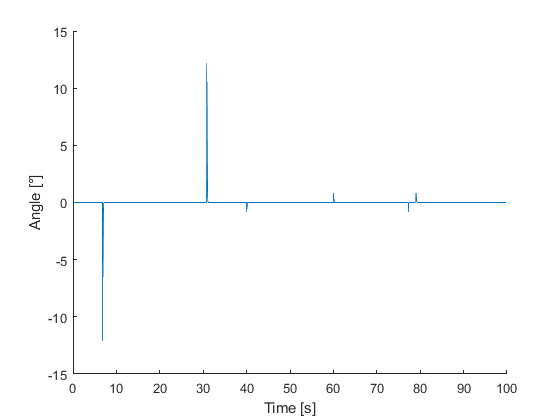

figure
hold on
plot(tout, various_m_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

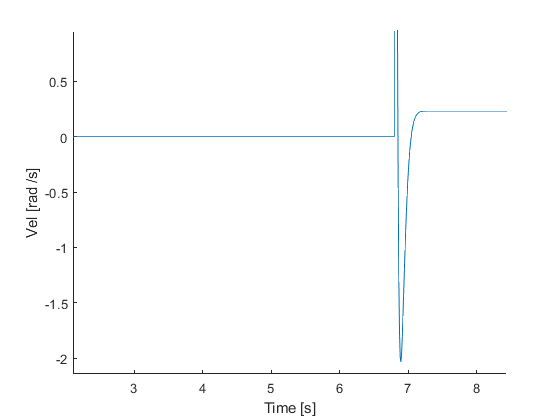


figure
hold on
plot(tout, various_vel_sim)
xlabel('Time [s]')
ylabel('Vel [rad /s]')

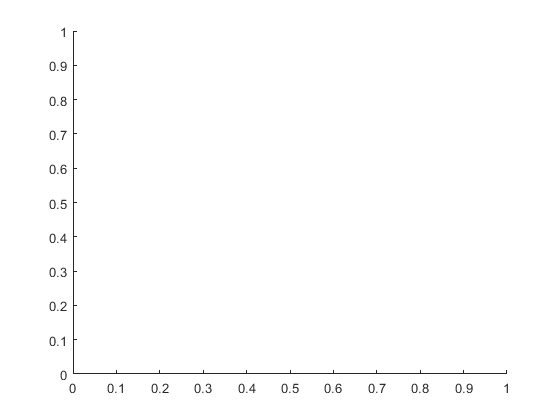



figure
hold on

plot(tout, various_l_sim)

Unrecognized function or variable 'various_l_sim'.

xlabel('Time [s]')
ylabel('Angle [°]')

legend('l = 2','l=4.5','l=7')

figure
hold on
plot(tout, various_b_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('b = 0','b=5','b=10')

% definizione sistema
s = tf('s');
l_rlocus = 1:0.5:7;

figure
hold on
sgrid on
for i=1:length(l_rlocus)
    G_s = (-1/g * s) / (l_rlocus(i)/g * s^2 + b_sim/(m_sim*l_rlocus(i)*g) * s + 1);
    rlocus(-G_s)
end

% simulazione
% smorzamento = b/(2m*sqrt(gL^3))
% puls = sqrt(g/l)

t_end = 100;
Ts = 1/100;
control_on = 1;
b_sim = b(1);
l_sim = l(3);
m_sim = m(3);

Kp_v = -[1 11 100];

%simulazione al variare di m (l = 7m b = 0)
for i = 1: length(Kp_v)
    Kp = Kp_v(i);
    
    sim  CarroponteSim
    various_Kp_sim_vel(i,:) = vel_out;
    various_Kp_sim(i,:) = sim_out;
end


figure
subplot 211
hold on
plot(tout, various_Kp_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Kp = 1','Kp=10','Kp=100')

subplot 212
hold on
plot(tout, various_Kp_sim_vel)
xlabel('Time [s]')
ylabel('Speed []')

legend('Kp = 1','Kp=10','Kp=100')
